**Least Squares**

1, 2 load data and plot 15 points

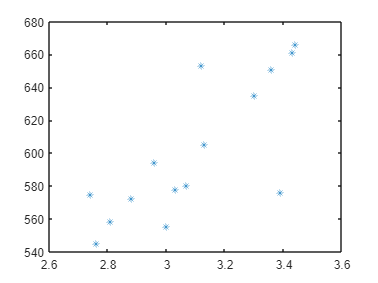

load lawdata.mat
plot(gpa, lsat, '*')

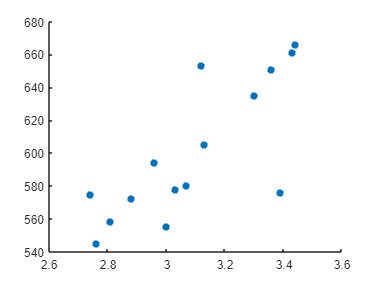

scatter(gpa, lsat, "filled")

3 fit a linear model

% contruct y and A
y_l = lsat

y_l =    576
   635
   558
   578
   666
   580
   555
   661
   651
   605


x0 = ones(15, 1)

x0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


A_l = horzcat(x0, gpa)

A_l =     1.0000    3.3900
    1.0000    3.3000
    1.0000    2.8100
    1.0000    3.0300
    1.0000    3.4400
    1.0000    3.0700
    1.0000    3.0000
    1.0000    3.4300
    1.0000    3.3600
    1.0000    3.1300



% construct y* and A*
Astar_l = A'*A

Astar_l =    15.0000   46.4200
   46.4200  144.4846


ystar_l = A'*y

ystar_l =         9004
       27975



% solve
% look into mldivide i
% you are interested in
% details of \
c_l = Astar_l\ystar_l

c_l =   187.8996
  133.2509


4 fit a quadratic model

% construct y and A
y_q = lsat

y_q =    576
   635
   558
   578
   666
   580
   555
   661
   651
   605


x0 = ones(15, 1)

x0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


x1 = gpa

x1 =     3.3900
    3.3000
    2.8100
    3.0300
    3.4400
    3.0700
    3.0000
    3.4300
    3.3600
    3.1300


x2 = gpa.^2

x2 =    11.4921
   10.8900
    7.8961
    9.1809
   11.8336
    9.4249
    9.0000
   11.7649
   11.2896
    9.7969


A_q = horzcat(x0, x1, x2)

A_q =     1.0000    3.3900   11.4921
    1.0000    3.3000   10.8900
    1.0000    2.8100    7.8961
    1.0000    3.0300    9.1809
    1.0000    3.4400   11.8336
    1.0000    3.0700    9.4249
    1.0000    3.0000    9.0000
    1.0000    3.4300   11.7649
    1.0000    3.3600   11.2896
    1.0000    3.1300    9.7969



% contruct A* and y*
Astar_q = A_q'*A_q

Astar_q = 1.0e+03 *

    0.0150    0.0464    0.1445
    0.0464    0.1445    0.4523
    0.1445    0.4523    1.4237


ystar_q = A_q'*y_q

ystar_q = 1.0e+04 *

    0.9004
    2.7975
    8.7417



% solve
c_q = Astar_q\ystar_q

c_q =   517.2826
  -80.2953
   34.4124


5 fit a cubic model

% construct y and A
y_c = lsat

y_c =    576
   635
   558
   578
   666
   580
   555
   661
   651
   605


x0 = ones(15, 1)

x0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


x1 = gpa

x1 =     3.3900
    3.3000
    2.8100
    3.0300
    3.4400
    3.0700
    3.0000
    3.4300
    3.3600
    3.1300


x2 = gpa.^2

x2 =    11.4921
   10.8900
    7.8961
    9.1809
   11.8336
    9.4249
    9.0000
   11.7649
   11.2896
    9.7969


x3 = gpa.^3

x3 =    38.9582
   35.9370
   22.1880
   27.8181
   40.7076
   28.9344
   27.0000
   40.3536
   37.9331
   30.6643


A_c = horzcat(x0, x1, x2, x3)

A_c =     1.0000    3.3900   11.4921   38.9582
    1.0000    3.3000   10.8900   35.9370
    1.0000    2.8100    7.8961   22.1880
    1.0000    3.0300    9.1809   27.8181
    1.0000    3.4400   11.8336   40.7076
    1.0000    3.0700    9.4249   28.9344
    1.0000    3.0000    9.0000   27.0000
    1.0000    3.4300   11.7649   40.3536
    1.0000    3.3600   11.2896   37.9331
    1.0000    3.1300    9.7969   30.6643



% contruct A* and y*
Astar_c = A_c'*A_c

Astar_c = 1.0e+04 *

    0.0015    0.0046    0.0144    0.0452
    0.0046    0.0144    0.0452    0.1424
    0.0144    0.0452    0.1424    0.4506
    0.0452    0.1424    0.4506    1.4337


ystar_c = A_c'*y_c

ystar_c = 1.0e+05 *

    0.0900
    0.2797
    0.8742
    2.7471



% solve
c_c = Astar_c\ystar_c

c_c = 1.0e+04 *

    1.2988
   -1.2296
    0.4010
   -0.0430


6, 7 plot on same figure

skipped 6b

% linear data
x = 2.7:0.01:3.5

x =     2.7000    2.7100    2.7200    2.7300    2.7400    2.7500    2.7600    2.7700    2.7800    2.7900    2.8000    2.8100    2.8200    2.8300    2.8400    2.8500    2.8600    2.8700    2.8800    2.8900    2.9000    2.9100    2.9200    2.9300    2.9400    2.9500    2.9600    2.9700    2.9800    2.9900    3.0000    3.0100    3.0200    3.0300    3.0400    3.0500    3.0600    3.0700    3.0800    3.0900    3.1000    3.1100    3.1200    3.1300    3.1400    3.1500    3.1600    3.1700    3.1800    3.1900


c_l

c_l =   187.8996
  133.2509


gpa

gpa =     3.3900
    3.3000
    2.8100
    3.0300
    3.4400
    3.0700
    3.0000
    3.4300
    3.3600
    3.1300


y_lin = c_l(1) + (c_l(2)).*x

y_lin =   547.6770  549.0095  550.3420  551.6745  553.0070  554.3395  555.6720  557.0045  558.3371  559.6696  561.0021  562.3346  563.6671  564.9996  566.3321  567.6646  568.9971  570.3296  571.6621  572.9947  574.3272  575.6597  576.9922  578.3247  579.6572  580.9897  582.3222  583.6547  584.9872  586.3197  587.6522  588.9848  590.3173  591.6498  592.9823  594.3148  595.6473  596.9798  598.3123  599.6448  600.9773  602.3098  603.6424  604.9749  606.3074  607.6399  608.9724  610.3049  611.6374  612.9699


y_lin = y_lin'

y_lin =   547.6770
  549.0095
  550.3420
  551.6745
  553.0070
  554.3395
  555.6720
  557.0045
  558.3371
  559.6696



% quadratic data
y_quad = c_q(1) + c_q(2).*x + c_q(3).*(x.^2)

y_quad =   551.3520  552.4108  553.4764  554.5490  555.6284  556.7147  557.8078  558.9079  560.0148  561.1287  562.2494  563.3769  564.5114  565.6528  566.8010  567.9561  569.1181  570.2870  571.4627  572.6454  573.8349  575.0313  576.2346  577.4448  578.6619  579.8858  581.1166  582.3543  583.5989  584.8504  586.1087  587.3740  588.6461  589.9251  591.2110  592.5037  593.8034  595.1099  596.4233  597.7436  599.0708  600.4049  601.7458  603.0936  604.4483  605.8099  607.1784  608.5537  609.9360  611.3251



% cubic data
y_cube = c_c(1) + c_c(2).*x + c_c(3).*(x.^2) + c_c(4).*(x.^3)

y_cube =   560.4928  560.1191  559.8486  559.6786  559.6065  559.6299  559.7460  559.9523  560.2463  560.6254  561.0869  561.6283  562.2470  562.9405  563.7062  564.5414  565.4437  566.4104  567.4389  568.5267  569.6712  570.8698  572.1199  573.4190  574.7645  576.1538  577.5843  579.0534  580.5586  582.0973  583.6668  585.2648  586.8884  588.5352  590.2026  591.8881  593.5889  595.3026  597.0266  598.7583  600.4951  602.2344  603.9737  605.7104  607.4418  609.1655  610.8789  612.5792  614.2641  615.9309


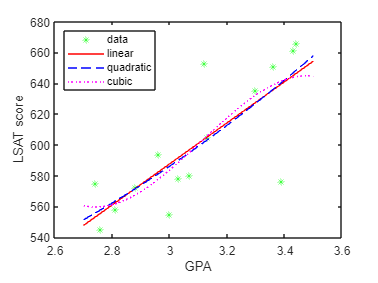


plot(gpa, lsat, "g*")
hold on
plot(x, y_lin, "red-")
plot(x, y_quad, "blue--")
plot(x, y_cube, "magenta:")
hold off

% labels
xlabel("GPA")
ylabel("LSAT score")
legend("data", "linear", "quadratic", "cubic", "location", "northwest")

Error vector

e_l = y_l - A_l*c_l

e_l =   -63.6201
    7.3725
   -4.3346
  -13.6498
   19.7174
  -16.9798
  -32.6522
   16.0499
   15.3774
    0.0251


e_q = y_q - A_q*c_q

e_q =   -64.5528
    7.9403
   -5.3769
  -11.9251
   17.7101
  -15.1099
  -31.1087
   14.2713
   15.0068
    1.9064


e_c = y_c - A_c*c_c

e_c =   -65.4958
    2.6661
   -3.6283
  -10.5352
   21.8227
  -15.3026
  -28.6668
   17.1990
   12.0008
   -0.7104


Mean Squared Error

MSE_l = cumsum(e_l.^2);
MSE_lin = MSE_l(end)/length(e_l)

MSE_lin = 647.6362

MSE_q = cumsum(e_q.^2);
MSE_quad = MSE_q(end)/length(e_q)

MSE_quad = 645.0679

MSE_c = cumsum(e_c.^2);
MSE_cub = MSE_c(end)/length(e_c)

MSE_cub = 636.1159

Display MSE and answer questions

disp(MSE_lin)

  647.6362



disp(MSE_quad)

  645.0679



disp(MSE_cub)

  636.1159



The cubic function has the lowest MSE because the curve changes the most allowing

it to adapt best to the data points. This is not however the method I would recommend for

predicting scores because it becomes really bad the moment you go outside of the range

of data points because it cuves up or down unlike how you would think the actual data to 

act. I would recommend the linear model because it's MSE is not that much higher than

the cubic one and it seems like a more likely relationship for the given data.